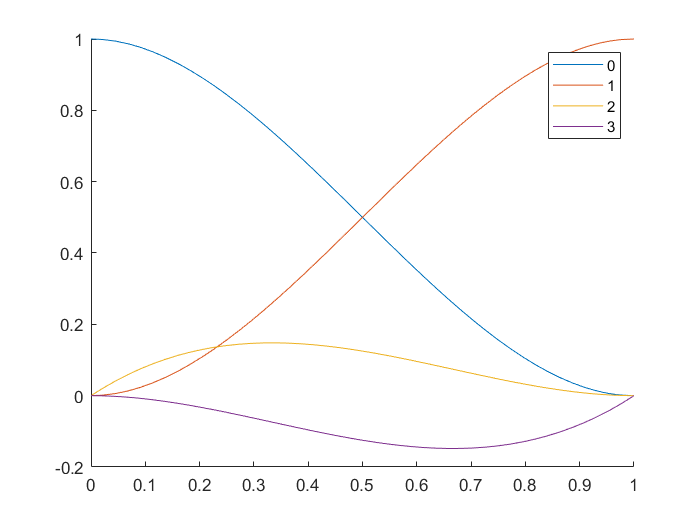

clear; 

syms h u t u0 u1 f0 f1

b0 = getPoly(t, 1, [1,0,0,0]');
b1 = getPoly(t, 1, [0,1,0,0]');
b2 = getPoly(t, 1, [0,0,1,0]');
b3 = getPoly(t, 1, [0,0,0,1]');
figure(1); clf;hold on;
fplot(b0,[0,1])
fplot(b1,[0,1])
fplot(b2,[0,1])
fplot(b3,[0,1])
hold off;
legend('0','1','2','3');

## integration

syms alpha v0 v1 v2
bases(t) = [1,t,t^2];
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

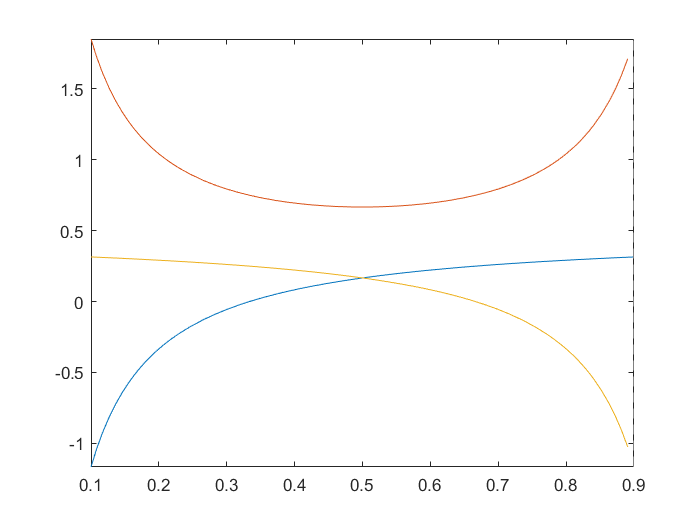

fplot(weights, [0.1,0.9])

## input

u_mid = [b0(alpha),b1(alpha),b2(alpha)*h,b3(alpha)*h] * transpose([u0,u1,f0,f1])

$$u\_mid = u_{0}\,\left(2\,\alpha^{3}-3\,\alpha^{2}+1\right)+u_{1}\,\left(3\,\alpha^{2}-2\,\alpha^{3}\right)-f_{1}\,h\,\left(\alpha^{2}-\alpha^{3}\right)+f_{0}\,h\,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)$$

syms f_mid;
incre = weights * [f0; f_mid; f1] * h;


## linear stability

syms lambda kappa
u_mid_lam = subs(u_mid, [f0,f1],[u0,u1] * lambda);

incre_lam = collect(subs(expand(incre), [f0,f_mid,f1], [u0*lambda,u_mid_lam*lambda,u1*lambda]), [u0,u1])

$$incre\_lam = \begin{array}{l} \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }+\frac{h\,\lambda \,\left(-3\,\alpha^{2}+2\,\alpha^{3}+h\,\lambda \,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)+1\right)}{\sigma_{1}}\right)\,u_{0}+\left(\frac{h\,\lambda }{2}+\frac{h\,\lambda }{6\,\left(\alpha -1\right)}-\frac{h\,\lambda \,\left(2\,\alpha^{3}-3\,\alpha^{2}+h\,\lambda \,\left(\alpha^{2}-\alpha^{3}\right)\right)}{\sigma_{1}}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=\left(\alpha -\alpha^{2}\right)\,6 \end{array}$$

K = subs(simplify(solve(incre_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K = -\frac{4\,\kappa -2\,\alpha \,\kappa -\alpha \,\kappa^{2}+\kappa^{2}+6}{2\,\kappa +2\,\alpha \,\kappa -\alpha \,\kappa^{2}-6}$$

## stablility region

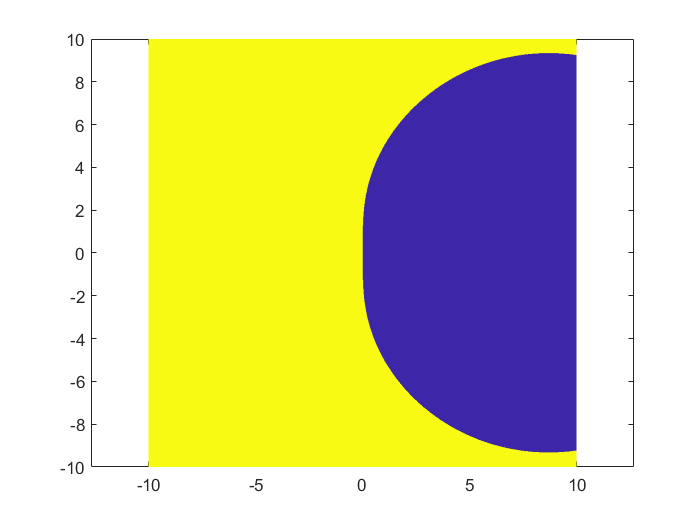

test_range = 10;
rSamp = linspace(-test_range,test_range,1000);
iSamp = linspace(-test_range,test_range,1000);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa, alpha]));
alphatest = 0.6667;
KM = abs(Kf(zSampM, alphatest));
p = pcolor(rSampM,iSampM, double(KM < 1));
p.EdgeColor = 'none';
axis equal;

function po = getPoly(t, h, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(0); bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end




